close all
clear variables


spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');


lambdaPr = 656.28; %нм 
speedOfLight = 299792.458; % км/с

nstars = size(starNames, 1);
nobs = size(spectra, 1);
lambda_end = lambdaStart + (nobs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambda_end)';


[sHa, idx] = min(spectra);
lambdaHa = lambda (idx);

z = lambdaHa / lambdaPr - 1;
speed = z * speedOfLight;


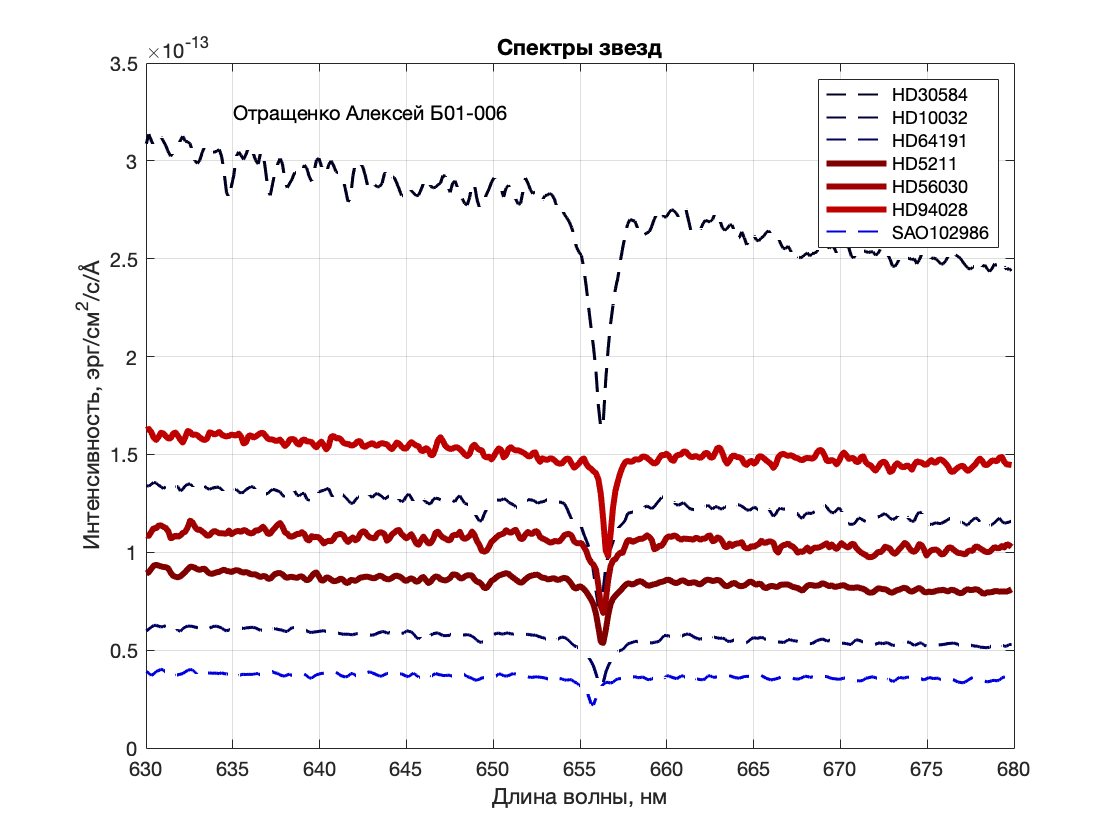


fg1 = figure;
for j1 = 1 : 1 : nstars
    if speed(j1, 1) > 0
        plot(lambda, spectra(:, j1), 'LineWidth', 3, 'Color', [j1/8 0 0])
        hold on
    else
        plot(lambda, spectra(:, j1), "--", 'LineWidth', 1, 'Color', [0 0 j1/8])
        hold on
    end
end

text (635, 3.25*10^-13, 'Отращенко Алексей Б01-006')
set(gcf, 'visible', 'on');
xlabel ('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/', char(197)])
title ('Спектры звезд')
grid on
legend(starNames, 'Location', 'northeast')
hold off
movaway = starNames(speed > 0);
saveas(fg1, 'spectrastars.png')